# 1. Load and Inspect Electricity Data

clear
clc
close all
scriptPath = matlab.desktop.editor.getActiveFilename;
codeFolder = fileparts(scriptPath);
projectFolder = fileparts(codeFolder);
disp("Live Script location:")

Live Script location:


disp(scriptPath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\code\load_forcasting_project.mlx



disp("Project folder:")

Project folder:


disp(projectFolder)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project


dataFile = fullfile(projectFolder,"data","electricityclient.mat");

disp("Dataset location:")

Dataset location:


disp(dataFile)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\data\electricityclient.mat


if ~isfile(dataFile)
    error('The electricity dataset is missing from the data folder.');
end
load(dataFile,"usagedata")

fprintf("Number of observations: %d\n",height(usagedata))

Number of observations: 26304


fprintf("Starting time: %s\n",string(usagedata.Time(1)))

Starting time: 2012-01-01 00:00:00


fprintf("Ending time: %s\n",string(usagedata.Time(end)))

Ending time: 2014-12-31 23:00:00



head(usagedata)

           Time            Electricity
    ___________________    ___________

    2012-01-01 00:00:00      263.39   
    2012-01-01 01:00:00      340.03   
    2012-01-01 02:00:00      309.52   
    2012-01-01 03:00:00      210.57   
    2012-01-01 04:00:00      161.46   
    2012-01-01 05:00:00      159.97   
    2012-01-01 06:00:00      179.32   
    2012-01-01 07:00:00      165.18   



## 2. Data Quality Checks

%% 2. Data Quality Checks

% Count missing electricity readings
missingLoad = sum(ismissing(usagedata.Electricity));

% Count negative electricity readings
negativeLoad = sum(usagedata.Electricity < 0);

% Count duplicate timestamps
numberOfTimes = height(usagedata);
numberOfUniqueTimes = numel(unique(usagedata.Time));
duplicateTimes = numberOfTimes-numberOfUniqueTimes;

% Calculate the time between consecutive observations
timeIntervals = diff(usagedata.Time);
mostCommonInterval = mode(timeIntervals);

% Count intervals that are not exactly one hour
irregularIntervals = sum(timeIntervals ~= hours(1));

% Calculate descriptive statistics
minimumLoad = min(usagedata.Electricity);
maximumLoad = max(usagedata.Electricity);
averageLoad = mean(usagedata.Electricity);
medianLoad = median(usagedata.Electricity);

% Display the results
fprintf("Missing electricity values: %d\n",missingLoad)

Missing electricity values: 0


fprintf("Negative electricity values: %d\n",negativeLoad)

Negative electricity values: 0


fprintf("Duplicate timestamps: %d\n",duplicateTimes)

Duplicate timestamps: 0


fprintf("Most common time interval: %s\n", ...
    string(mostCommonInterval))

Most common time interval: 01:00:00


fprintf("Intervals different from one hour: %d\n", ...
    irregularIntervals)

Intervals different from one hour: 0



fprintf("\nConsumption statistics:\n")


Consumption statistics:


fprintf("Minimum consumption: %.2f kWh\n",minimumLoad)

Minimum consumption: 0.00 kWh


fprintf("Maximum consumption: %.2f kWh\n",maximumLoad)

Maximum consumption: 495.54 kWh


fprintf("Average consumption: %.2f kWh\n",averageLoad)

Average consumption: 188.26 kWh


fprintf("Median consumption: %.2f kWh\n",medianLoad)

Median consumption: 180.80 kWh


## 3. Visualize the Complete Dataset

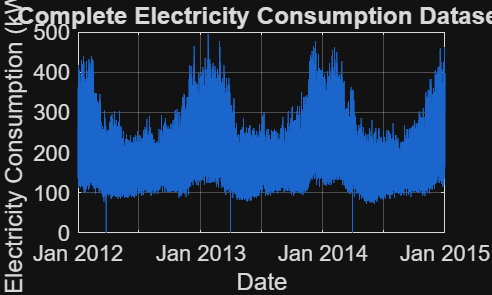

%% 3. Visualize the Complete Dataset

% Create a folder for saved graphs
figuresFolder = fullfile(projectFolder,"figures");

if ~isfolder(figuresFolder)
    mkdir(figuresFolder)
end

% Plot all hourly electricity-consumption observations
figure

plot(usagedata.Time, ...
    usagedata.Electricity, ...
    "Color",[0.10 0.40 0.80])

xlabel("Date")
ylabel("Electricity Consumption (kWh)")
title("Complete Electricity Consumption Dataset")
grid on

set(gca,"FontSize",11)

% Save the graph as a high-resolution PNG image
completeFigurePath = fullfile( ...
    figuresFolder,"complete_dataset.png");

exportgraphics(gcf,completeFigurePath, ...
    "Resolution",300)


disp("Complete dataset graph saved at:")

Complete dataset graph saved at:


disp(completeFigurePath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\figures\complete_dataset.png


## 4. Visualize Two Weeks of Electricity Consumption

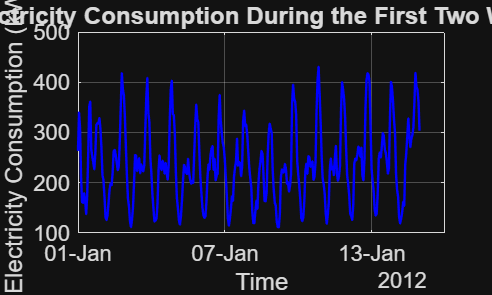

%% 4. Visualize Two Weeks of Electricity Consumption

% Specify the period to display
hoursPerDay = 24;
numberOfDays = 14;
numberOfHours = hoursPerDay*numberOfDays;

% Ensure the selected period does not exceed the dataset
numberOfHours = min(numberOfHours,height(usagedata));

% Plot the first two weeks
figure

plot(usagedata.Time(1:numberOfHours), ...
    usagedata.Electricity(1:numberOfHours), ...
    "b","LineWidth",1.2)

xlabel("Time")
ylabel("Electricity Consumption (kWh)")
title("Electricity Consumption During the First Two Weeks")
grid on

set(gca,"FontSize",11)
xtickformat("dd-MMM")

% Save the graph
twoWeekFigurePath = fullfile( ...
    figuresFolder,"two_week_consumption.png");

exportgraphics(gcf,twoWeekFigurePath, ...
    "Resolution",300)


disp("Two-week graph saved at:")

Two-week graph saved at:


disp(twoWeekFigurePath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\figures\two_week_consumption.png


## 5. Create Forecasting Features

%% 5. Create Forecasting Features

% Extract timestamps and electricity consumption
time = usagedata.Time;
electricity = usagedata.Electricity;

% Create historical-consumption features
numberOfObservations = length(electricity);

lag1 = NaN(numberOfObservations,1);
lag24 = NaN(numberOfObservations,1);
lag168 = NaN(numberOfObservations,1);

lag1(2:end) = electricity(1:end-1);
lag24(25:end) = electricity(1:end-24);
lag168(169:end) = electricity(1:end-168);

% Create calendar features
hourNumber = hour(time);
weekdayNumber = weekday(time);
monthNumber = month(time);

% Saturday and Sunday are treated as weekends
isWeekend = weekdayNumber == 1 | weekdayNumber == 7;

% Combine all input features into one matrix
X = [lag1, ...
    lag24, ...
    lag168, ...
    hourNumber, ...
    weekdayNumber, ...
    monthNumber, ...
    double(isWeekend)];

% Store descriptive feature names
featureNames = ["Lag1", ...
    "Lag24", ...
    "Lag168", ...
    "Hour", ...
    "Weekday", ...
    "Month", ...
    "Weekend"];

% The target is electricity consumption at the current hour
Y = electricity;

% Remove rows whose lagged values are unavailable
validRows = all(~isnan(X),2) & ~isnan(Y);

X = X(validRows,:);
Y = Y(validRows);
timeValid = time(validRows);

% Confirm that predictors and targets have equal observations
assert(size(X,1) == length(Y), ...
    'The numbers of predictor and target observations do not match.')

% Display dataset dimensions
fprintf("Original observations: %d\n",height(usagedata))

Original observations: 26304


fprintf("Usable observations: %d\n",length(Y))

Usable observations: 26136


fprintf("Number of input features: %d\n",size(X,2))

Number of input features: 7


fprintf("Removed observations: %d\n", ...
    height(usagedata)-length(Y))

Removed observations: 168



% Display the first five prepared observations
previewRows = 1:5;

featurePreview = array2table( ...
    X(previewRows,:), ...
    "VariableNames",featureNames);

featurePreview.Time = timeValid(previewRows);
featurePreview.ActualElectricity = Y(previewRows);

featurePreview = movevars( ...
    featurePreview,"Time","Before",1);

disp(featurePreview)

           Time             Lag1     Lag24     Lag168    Hour    Weekday    Month    Weekend    ActualElectricity
    ___________________    ______    ______    ______    ____    _______    _____    _______    _________________

    2012-01-08 00:00:00     261.9    246.28    263.39     0         1         1         1            229.91      
    2012-01-08 01:00:00    229.91    210.57    340.03     1         1         1         1            209.08      
    2012-01-08 02:00:00    209.08    172.62    309.52     2         1         1         1            190.48      
    2012-01-08 03:00:00    190.48    130.21    210.57     3         1         1         1            141.37      
    2012-

## 6. Split Data Chronologically

%% 6. Split Data Chronologically

% Count usable observations
totalObservations = size(X,1);

% Define the chronological split positions
trainingEnd = floor(0.70*totalObservations);
validationEnd = floor(0.85*totalObservations);

% Training set: earliest 70 percent
XTrain = X(1:trainingEnd,:);
YTrain = Y(1:trainingEnd);
timeTrain = timeValid(1:trainingEnd);

% Validation set: following 15 percent
XValidation = X(trainingEnd+1:validationEnd,:);
YValidation = Y(trainingEnd+1:validationEnd);
timeValidation = timeValid(trainingEnd+1:validationEnd);

% Test set: latest 15 percent
XTest = X(validationEnd+1:end,:);
YTest = Y(validationEnd+1:end);
timeTest = timeValid(validationEnd+1:end);

% Display split sizes
fprintf("Total usable observations: %d\n",totalObservations)

Total usable observations: 26136


fprintf("Training observations: %d\n",length(YTrain))

Training observations: 18295


fprintf("Validation observations: %d\n",length(YValidation))

Validation observations: 3920


fprintf("Testing observations: %d\n",length(YTest))

Testing observations: 3921



% Display date ranges
fprintf("\nTraining period:\n")


Training period:


fprintf("%s to %s\n", ...
    string(timeTrain(1)),string(timeTrain(end)))

2012-01-08 00:00:00 to 2014-02-08 06:00:00



fprintf("\nValidation period:\n")


Validation period:


fprintf("%s to %s\n", ...
    string(timeValidation(1)),string(timeValidation(end)))

2014-02-08 07:00:00 to 2014-07-21 14:00:00



fprintf("\nTesting period:\n")


Testing period:


fprintf("%s to %s\n", ...
    string(timeTest(1)),string(timeTest(end)))

2014-07-21 15:00:00 to 2014-12-31 23:00:00


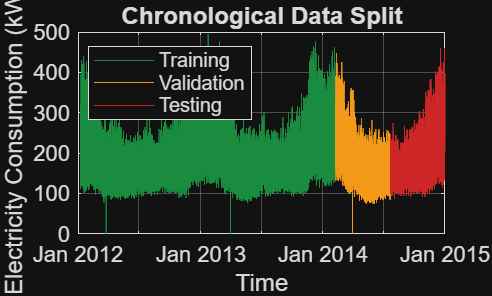


% Confirm that no observations were lost
splitTotal = length(YTrain) + ...
    length(YValidation) + ...
    length(YTest);

assert(splitTotal == totalObservations, ...
    'Some observations were lost during data splitting.')

% Plot the three chronological periods
figure

plot(timeTrain,YTrain, ...
    "Color",[0.10 0.55 0.25])
hold on

plot(timeValidation,YValidation, ...
    "Color",[0.95 0.60 0.10])

plot(timeTest,YTest, ...
    "Color",[0.80 0.15 0.15])

xlabel("Time")
ylabel("Electricity Consumption (kWh)")
title("Chronological Data Split")
legend("Training","Validation","Testing", ...
    "Location","best")
grid on

set(gca,"FontSize",11)

% Save the graph
splitFigurePath = fullfile( ...
    figuresFolder,"chronological_data_split.png");

exportgraphics(gcf,splitFigurePath, ...
    "Resolution",300)


disp("Data-split graph saved at:")

Data-split graph saved at:


disp(splitFigurePath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\figures\chronological_data_split.png


## 7. Create and Evaluate Baseline Forecasts

%% 7. Create and Evaluate Baseline Forecasts

% Baseline 1: use the same hour from yesterday
predictionYesterday = XTest(:,2);

% Baseline 2: use the same hour from last week
predictionLastWeek = XTest(:,3);

% Calculate yesterday-baseline errors
errorYesterday = YTest-predictionYesterday;

maeYesterday = mean(abs(errorYesterday));
rmseYesterday = sqrt(mean(errorYesterday.^2));

nonzeroYesterday = abs(YTest) > eps;

mapeYesterday = mean( ...
    abs(errorYesterday(nonzeroYesterday) ./ ...
    YTest(nonzeroYesterday))) * 100;

% Calculate last-week-baseline errors
errorLastWeek = YTest-predictionLastWeek;

maeLastWeek = mean(abs(errorLastWeek));
rmseLastWeek = sqrt(mean(errorLastWeek.^2));

nonzeroLastWeek = abs(YTest) > eps;

mapeLastWeek = mean( ...
    abs(errorLastWeek(nonzeroLastWeek) ./ ...
    YTest(nonzeroLastWeek))) * 100;

% Display the numerical results
fprintf("\nYesterday baseline results:\n")


Yesterday baseline results:


fprintf("MAE: %.3f kWh\n",maeYesterday)

MAE: 18.167 kWh


fprintf("RMSE: %.3f kWh\n",rmseYesterday)

RMSE: 25.529 kWh


fprintf("MAPE: %.2f %%\n",mapeYesterday)

MAPE: 9.93 %



fprintf("\nLast-week baseline results:\n")


Last-week baseline results:


fprintf("MAE: %.3f kWh\n",maeLastWeek)

MAE: 15.920 kWh


fprintf("RMSE: %.3f kWh\n",rmseLastWeek)

RMSE: 22.234 kWh


fprintf("MAPE: %.2f %%\n",mapeLastWeek)

MAPE: 8.43 %



% Create a comparison table
baselineModel = [
    "Same Hour Yesterday"
    "Same Hour Last Week"
];

baselineMAE = [
    maeYesterday
    maeLastWeek
];

baselineRMSE = [
    rmseYesterday
    rmseLastWeek
];

baselineMAPE = [
    mapeYesterday
    mapeLastWeek
];

baselineResults = table( ...
    baselineModel, ...
    baselineMAE, ...
    baselineRMSE, ...
    baselineMAPE, ...
    VariableNames=["Model","MAE","RMSE","MAPE"]);

disp(baselineResults)

            Model             MAE       RMSE      MAPE 
    _____________________    ______    ______    ______

    "Same Hour Yesterday"    18.167    25.529     9.931
    "Same Hour Last Week"     15.92    22.234    8.4327



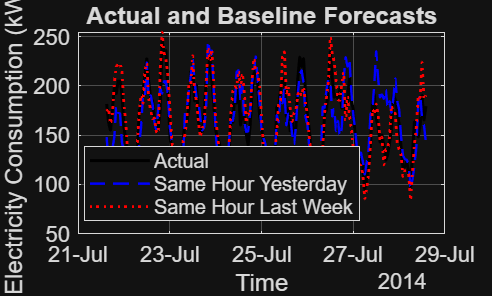


% Display one test week
displayHours = min(7*24,length(YTest));

figure

plot(timeTest(1:displayHours), ...
     YTest(1:displayHours), ...
     "k","LineWidth",1.5)

hold on

plot(timeTest(1:displayHours), ...
     predictionYesterday(1:displayHours), ...
     "b--","LineWidth",1.2)

plot(timeTest(1:displayHours), ...
     predictionLastWeek(1:displayHours), ...
     "r:","LineWidth",1.4)

xlabel("Time")
ylabel("Electricity Consumption (kWh)")
title("Actual and Baseline Forecasts")

legend("Actual", ...
       "Same Hour Yesterday", ...
       "Same Hour Last Week", ...
       "Location","best")

grid on
set(gca,"FontSize",11)
xtickformat("dd-MMM")

% Save the graph
baselineFigurePath = fullfile( ...
    figuresFolder,"baseline_forecasts.png");

exportgraphics(gcf,baselineFigurePath, ...
    "Resolution",300)


disp("Baseline graph saved at:")

Baseline graph saved at:


disp(baselineFigurePath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\figures\baseline_forecasts.png


## 8. Train and Evaluate Linear Regression

%% 8. Train and Evaluate Linear Regression

% Train the model using the earliest 70 percent of data
regressionModel = fitlm(XTrain,YTrain);

% Display learned coefficients and model information
disp(regressionModel)


Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)     -3.022       0.61026    -4.9519    7.4139e-07
    x1             0.30855     0.0041774     73.863             0
    x2             0.31573     0.0050941      61.98             0
    x3             0.36494     0.0051357     71.059             0
    x4             0.26723      0.026464     10.098    6.5234e-24
    x5             0.29756      0.068834     4.3228    1.5485e-05
    x6             0.30116      0.039248     7.6733      1.76e-14
    x7             -3.6883       0.30


% Predict the validation period
predictionRegressionValidation = predict( ...
    regressionModel,XValidation);

% Calculate validation errors
errorRegressionValidation = ...
    YValidation-predictionRegressionValidation;

maeRegressionValidation = ...
    mean(abs(errorRegressionValidation));

rmseRegressionValidation = ...
    sqrt(mean(errorRegressionValidation.^2));

validPercentageRows = abs(YValidation) > eps;

mapeRegressionValidation = mean( ...
    abs(errorRegressionValidation(validPercentageRows) ./ ...
    YValidation(validPercentageRows))) * 100;

% Display validation results
fprintf("\nLinear regression validation results:\n")


Linear regression validation results:


fprintf("MAE: %.3f kWh\n",maeRegressionValidation)

MAE: 13.309 kWh


fprintf("RMSE: %.3f kWh\n",rmseRegressionValidation)

RMSE: 17.862 kWh


fprintf("MAPE: %.2f %%\n",mapeRegressionValidation)

MAPE: 7.40 %



% Predict the final unseen test period
predictionRegression = predict(regressionModel,XTest);

% Calculate test errors
errorRegression = YTest-predictionRegression;

maeRegression = mean(abs(errorRegression));
rmseRegression = sqrt(mean(errorRegression.^2));

nonzeroRegression = abs(YTest) > eps;

mapeRegression = mean( ...
    abs(errorRegression(nonzeroRegression) ./ ...
    YTest(nonzeroRegression))) * 100;

% Display test results
fprintf("\nLinear regression test results:\n")


Linear regression test results:


fprintf("MAE: %.3f kWh\n",maeRegression)

MAE: 12.347 kWh


fprintf("RMSE: %.3f kWh\n",rmseRegression)

RMSE: 17.040 kWh


fprintf("MAPE: %.2f %%\n",mapeRegression)

MAPE: 6.64 %



% Compare regression with both baseline forecasts
comparisonModel = [
    "Same Hour Yesterday"
    "Same Hour Last Week"
    "Linear Regression"
];

comparisonMAE = [
    maeYesterday
    maeLastWeek
    maeRegression
];

comparisonRMSE = [
    rmseYesterday
    rmseLastWeek
    rmseRegression
];

comparisonMAPE = [
    mapeYesterday
    mapeLastWeek
    mapeRegression
];

regressionComparison = table( ...
    comparisonModel, ...
    comparisonMAE, ...
    comparisonRMSE, ...
    comparisonMAPE, ...
    VariableNames=["Model","MAE","RMSE","MAPE"]);

disp(regressionComparison)

            Model             MAE       RMSE      MAPE 
    _____________________    ______    ______    ______

    "Same Hour Yesterday"    18.167    25.529     9.931
    "Same Hour Last Week"     15.92    22.234    8.4327
    "Linear Regression"      12.347     17.04    6.6409



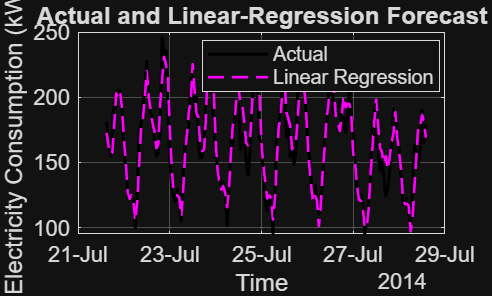


% Plot the first test week
displayHours = min(7*24,length(YTest));

figure

plot(timeTest(1:displayHours), ...
     YTest(1:displayHours), ...
     "k","LineWidth",1.5)

hold on

plot(timeTest(1:displayHours), ...
     predictionRegression(1:displayHours), ...
     "m--","LineWidth",1.3)

xlabel("Time")
ylabel("Electricity Consumption (kWh)")
title("Actual and Linear-Regression Forecast")

legend("Actual","Linear Regression", ...
    "Location","best")

grid on
set(gca,"FontSize",11)
xtickformat("dd-MMM")

% Save the graph
regressionFigurePath = fullfile( ...
    figuresFolder,"actual_vs_regression.png");

exportgraphics(gcf,regressionFigurePath, ...
    "Resolution",300)


disp("Regression graph saved at:")

Regression graph saved at:


disp(regressionFigurePath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\figures\actual_vs_regression.png


## 9. Train and Evaluate Artificial Neural Network

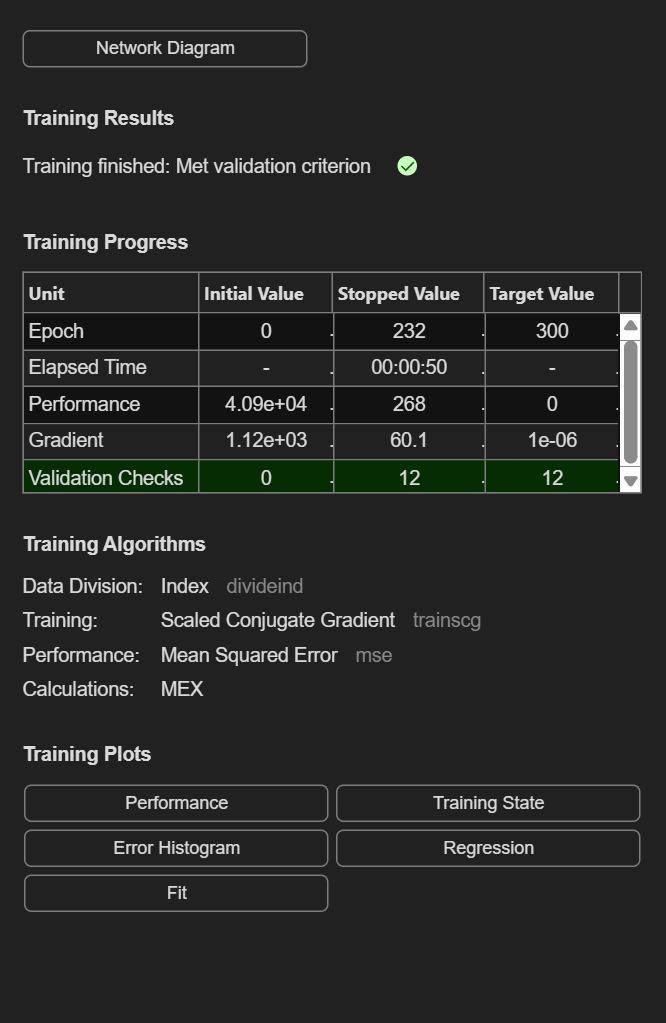

%% 9. Train and Evaluate Artificial Neural Network

% Calculate normalization parameters from training data only
inputMean = mean(XTrain,1);
inputStandardDeviation = std(XTrain,0,1);

% Avoid division by zero
inputStandardDeviation(inputStandardDeviation == 0) = 1;

% Normalize predictors
XTrainNormalized = ...
    (XTrain-inputMean)./inputStandardDeviation;

XValidationNormalized = ...
    (XValidation-inputMean)./inputStandardDeviation;

XTestNormalized = ...
    (XTest-inputMean)./inputStandardDeviation;

% Combine training and validation observations
XDevelopmentANN = [
    XTrainNormalized
    XValidationNormalized
];

YDevelopmentANN = [
    YTrain
    YValidation
];

% Create an ANN with two hidden layers
ann = fitnet([20 10],"trainscg");

% Disable automatic processing because normalization is manual
ann.inputs{1}.processFcns = {};
ann.outputs{ann.numLayers}.processFcns = {};

% Specify chronological training and validation indices
numberTrainingANN = size(XTrainNormalized,1);
numberDevelopmentANN = size(XDevelopmentANN,1);

ann.divideFcn = "divideind";

ann.divideParam.trainInd = 1:numberTrainingANN;

ann.divideParam.valInd = ...
    numberTrainingANN+1:numberDevelopmentANN;

ann.divideParam.testInd = [];

% Configure the training process
ann.performFcn = "mse";
ann.trainParam.epochs = 300;
ann.trainParam.max_fail = 12;
ann.trainParam.showWindow = true;

% Fix the random initialization for reproducibility
rng(42)

% Train the ANN
[ann,trainingRecord] = train( ...
    ann, ...
    XDevelopmentANN', ...
    YDevelopmentANN');


% Forecast the unseen test observations
predictionANN = ann(XTestNormalized')';

% Calculate test errors
errorANN = YTest-predictionANN;

maeANN = mean(abs(errorANN));
rmseANN = sqrt(mean(errorANN.^2));

nonzeroANN = abs(YTest) > eps;

mapeANN = mean( ...
    abs(errorANN(nonzeroANN)./YTest(nonzeroANN))) * 100;

% Display numerical results
fprintf("\nArtificial neural network test results:\n")


Artificial neural network test results:


fprintf("MAE: %.3f kWh\n",maeANN)

MAE: 11.121 kWh


fprintf("RMSE: %.3f kWh\n",rmseANN)

RMSE: 15.634 kWh


fprintf("MAPE: %.2f %%\n",mapeANN)

MAPE: 5.98 %


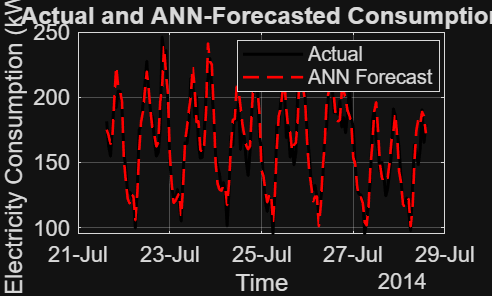


% Plot the first test week
displayHours = min(7*24,length(YTest));

figure

plot(timeTest(1:displayHours), ...
     YTest(1:displayHours), ...
     "k","LineWidth",1.5)

hold on

plot(timeTest(1:displayHours), ...
     predictionANN(1:displayHours), ...
     "r--","LineWidth",1.3)

xlabel("Time")
ylabel("Electricity Consumption (kWh)")
title("Actual and ANN-Forecasted Consumption")

legend("Actual","ANN Forecast", ...
    "Location","best")

grid on
set(gca,"FontSize",11)
xtickformat("dd-MMM")

% Save the graph
annFigurePath = fullfile( ...
    figuresFolder,"actual_vs_ann.png");

exportgraphics(gcf,annFigurePath, ...
    "Resolution",300)


disp("ANN graph saved at:")

ANN graph saved at:


disp(annFigurePath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\figures\actual_vs_ann.png


## 10. Compare All Forecasting Models

%% 10. Compare All Forecasting Models

% Store model names
modelNames = [
    "Same Hour Yesterday"
    "Same Hour Last Week"
    "Linear Regression"
    "Artificial Neural Network"
];

% Collect test metrics
allMAE = [
    maeYesterday
    maeLastWeek
    maeRegression
    maeANN
];

allRMSE = [
    rmseYesterday
    rmseLastWeek
    rmseRegression
    rmseANN
];

allMAPE = [
    mapeYesterday
    mapeLastWeek
    mapeRegression
    mapeANN
];

% Create final comparison table
finalResults = table( ...
    modelNames, ...
    allMAE, ...
    allRMSE, ...
    allMAPE, ...
    VariableNames=["Model","MAE_kWh","RMSE_kWh","MAPE_Percent"]);

disp(finalResults)

               Model               MAE_kWh    RMSE_kWh    MAPE_Percent
    ___________________________    _______    ________    ____________

    "Same Hour Yesterday"          18.167      25.529         9.931   
    "Same Hour Last Week"           15.92      22.234        8.4327   
    "Linear Regression"            12.347       17.04        6.6409   
    "Artificial Neural Network"    11.121      15.634        5.9786   




% Identify the model with the lowest test RMSE
[lowestRMSE,bestModelIndex] = min(allRMSE);
bestModelName = modelNames(bestModelIndex);

fprintf("\nBest model according to test RMSE:\n")


Best model according to test RMSE:


fprintf("%s\n",bestModelName)

Artificial Neural Network


fprintf("Lowest test RMSE: %.3f kWh\n",lowestRMSE)

Lowest test RMSE: 15.634 kWh



% Calculate ANN improvement relative to the stronger baseline
bestBaselineRMSE = min([rmseYesterday,rmseLastWeek]);

annImprovement = ...
    (bestBaselineRMSE-rmseANN)/bestBaselineRMSE*100;

fprintf("\nANN RMSE improvement over best baseline: %.2f %%\n", ...
    annImprovement)


ANN RMSE improvement over best baseline: 29.68 %


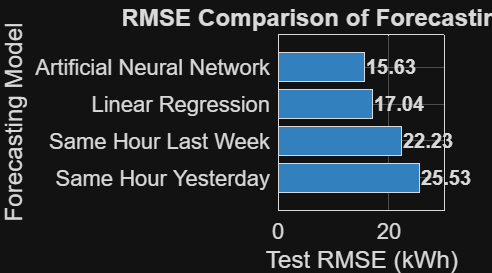


% Plot the RMSE comparison
% Create a clear horizontal RMSE comparison graph
figure("Position",[100 100 900 500])

modelCategories = categorical( ...
    modelNames,modelNames,"Ordinal",true);

barh(modelCategories,allRMSE, ...
    "FaceColor",[0.20 0.50 0.75])

xlabel("Test RMSE (kWh)")
ylabel("Forecasting Model")
title("RMSE Comparison of Forecasting Models")
grid on

set(gca,"FontSize",11)

% Write the RMSE value beside each bar
hold on

for modelIndex = 1:length(allRMSE)
    text(allRMSE(modelIndex)+0.3,modelIndex, ...
        sprintf("%.2f",allRMSE(modelIndex)), ...
        "VerticalAlignment","middle", ...
        "FontWeight","bold")
end

% Add space for numerical labels
xlim([0,max(allRMSE)*1.18])

% Create the results folder
resultsFolder = fullfile(projectFolder,"results");

if ~isfolder(resultsFolder)
    mkdir(resultsFolder)
end

% Save the numerical comparison
resultsTablePath = fullfile( ...
    resultsFolder,"model_comparison.csv");

writetable(finalResults,resultsTablePath)

% Save trained models and required preprocessing information
trainedModelsPath = fullfile( ...
    resultsFolder,"trained_forecasting_models.mat");

save(trainedModelsPath, ...
    "regressionModel", ...
    "ann", ...
    "inputMean", ...
    "inputStandardDeviation", ...
    "featureNames", ...
    "finalResults")

disp("Results saved at:")

Results saved at:


disp(resultsFolder)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\results


## 11. Analyze ANN Forecast Errors

%% 11. Analyze ANN Forecast Errors

% Calculate signed forecast errors
annError = YTest-predictionANN;

% Calculate error statistics
meanANNError = mean(annError);
errorStandardDeviation = std(annError);

% Locate the largest absolute forecast error
[maximumAbsoluteError,maximumErrorIndex] = ...
    max(abs(annError));

maximumErrorTime = timeTest(maximumErrorIndex);
actualAtMaximumError = YTest(maximumErrorIndex);
forecastAtMaximumError = predictionANN(maximumErrorIndex);

% Display error information
fprintf("\nANN error analysis:\n")


ANN error analysis:


fprintf("Mean error or bias: %.3f kWh\n",meanANNError)

Mean error or bias: -0.397 kWh



fprintf("Error standard deviation: %.3f kWh\n", ...
    errorStandardDeviation)

Error standard deviation: 15.631 kWh



fprintf("Maximum absolute error: %.3f kWh\n", ...
    maximumAbsoluteError)

Maximum absolute error: 118.593 kWh



fprintf("Time of maximum error: %s\n", ...
    string(maximumErrorTime))

Time of maximum error: 2014-10-26 01:00:00



fprintf("Actual consumption at that time: %.3f kWh\n", ...
    actualAtMaximumError)

Actual consumption at that time: 251.488 kWh



fprintf("ANN forecast at that time: %.3f kWh\n", ...
    forecastAtMaximumError)

ANN forecast at that time: 132.895 kWh


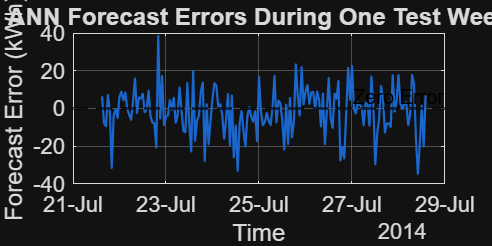


% Plot errors during the first test week
displayHours = min(7*24,length(annError));

figure("Position",[100 100 900 450])

plot(timeTest(1:displayHours), ...
    annError(1:displayHours), ...
    "Color",[0.10 0.40 0.80], ...
    "LineWidth",1.1)

hold on
yline(0,"k--","Zero Error","LineWidth",1.2)

xlabel("Time")
ylabel("Forecast Error (kWh)")
title("ANN Forecast Errors During One Test Week")
grid on

set(gca,"FontSize",11)
xtickformat("dd-MMM")

% Save the time-based error graph
annErrorFigurePath = fullfile( ...
    figuresFolder,"ann_error_over_time.png");

exportgraphics(gcf,annErrorFigurePath, ...
    "Resolution",300)

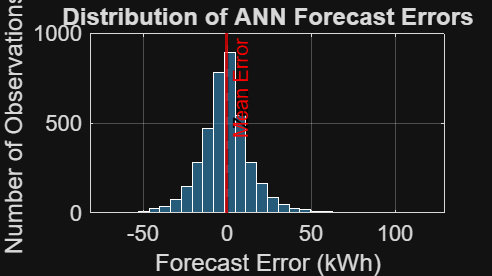


% Create an error-distribution histogram
figure("Position",[100 100 800 450])

histogram(annError,30, ...
    "FaceColor",[0.20 0.55 0.75], ...
    "EdgeColor","white")

hold on

xline(0,"k--","Zero Error","LineWidth",1.2)

xline(meanANNError,"r-", ...
    "Mean Error","LineWidth",1.5)

xlabel("Forecast Error (kWh)")
ylabel("Number of Observations")
title("Distribution of ANN Forecast Errors")
grid on

set(gca,"FontSize",11)

% Save the histogram
annHistogramPath = fullfile( ...
    figuresFolder,"ann_error_histogram.png");

exportgraphics(gcf,annHistogramPath, ...
    "Resolution",300)


disp("ANN error-analysis graphs saved successfully.")

ANN error-analysis graphs saved successfully.


## 12. Prepare Day-Ahead Forecasting Data

%% 12. Prepare Day-Ahead Forecasting Data

% Construct inputs available before the forecasted day begins
% Lag1 is excluded because actual future-day readings are unavailable
XDayAhead = [
    lag24, ...
    lag168, ...
    hourNumber, ...
    weekdayNumber, ...
    monthNumber, ...
    double(isWeekend)
    ];

% Define the target and corresponding timestamps
YDayAhead = electricity;
timeDayAhead = time;

% Store descriptive feature names
dayAheadFeatureNames = [
    "Lag24", ...
    "Lag168", ...
    "Hour", ...
    "Weekday", ...
    "Month", ...
    "Weekend"
    ];

% Remove rows with unavailable historical inputs
validDayAheadRows = ...
    all(~isnan(XDayAhead),2) & ...
    ~isnan(YDayAhead);

XDayAhead = XDayAhead(validDayAheadRows,:);
YDayAhead = YDayAhead(validDayAheadRows);
timeDayAhead = timeDayAhead(validDayAheadRows);

% Confirm the prepared dimensions
assert(size(XDayAhead,1) == length(YDayAhead), ...
    'Day-ahead inputs and targets have different lengths.')

fprintf("\nDay-ahead dataset information:\n")


Day-ahead dataset information:


fprintf("Usable observations: %d\n",length(YDayAhead))

Usable observations: 26136


fprintf("Number of input features: %d\n", ...
    size(XDayAhead,2))

Number of input features: 6



% Display the first five prepared observations
dayAheadPreviewRows = 1:5;

dayAheadPreview = array2table( ...
    XDayAhead(dayAheadPreviewRows,:), ...
    VariableNames=dayAheadFeatureNames);

dayAheadPreview.Time = ...
    timeDayAhead(dayAheadPreviewRows);

dayAheadPreview.ActualElectricity = ...
    YDayAhead(dayAheadPreviewRows);

dayAheadPreview = movevars( ...
    dayAheadPreview,"Time","Before",1);

disp(dayAheadPreview)

           Time            Lag24     Lag168    Hour    Weekday    Month    Weekend    ActualElectricity
    ___________________    ______    ______    ____    _______    _____    _______    _________________

    2012-01-08 00:00:00    246.28    263.39     0         1         1         1            229.91      
    2012-01-08 01:00:00    210.57    340.03     1         1         1         1            209.08      
    2012-01-08 02:00:00    172.62    309.52     2         1         1         1            190.48      
    2012-01-08 03:00:00    130.21    210.57     3         1         1         1            141.37      
    2012-01-08 04:00:00    114.58    161.46     4         1         1         1            119.79      

## 13. Train Day-Ahead Linear Regression

%% 13. Train Day-Ahead Linear Regression

% Count all prepared day-ahead observations
totalDayAheadObservations = size(XDayAhead,1);

% Calculate chronological split positions
dayAheadTrainingEnd = ...
    floor(0.70*totalDayAheadObservations);

dayAheadValidationEnd = ...
    floor(0.85*totalDayAheadObservations);

% Earliest 70 percent: training
XDayAheadTrain = ...
    XDayAhead(1:dayAheadTrainingEnd,:);

YDayAheadTrain = ...
    YDayAhead(1:dayAheadTrainingEnd);

% Following 15 percent: validation
XDayAheadValidation = ...
    XDayAhead(dayAheadTrainingEnd+1:dayAheadValidationEnd,:);

YDayAheadValidation = ...
    YDayAhead(dayAheadTrainingEnd+1:dayAheadValidationEnd);

% Latest 15 percent: final testing
XDayAheadTest = ...
    XDayAhead(dayAheadValidationEnd+1:end,:);

YDayAheadTest = ...
    YDayAhead(dayAheadValidationEnd+1:end);

timeDayAheadTest = ...
    timeDayAhead(dayAheadValidationEnd+1:end);

% Display split sizes
fprintf("\nDay-ahead chronological split:\n")


Day-ahead chronological split:



fprintf("Training observations: %d\n", ...
    length(YDayAheadTrain))

Training observations: 18295



fprintf("Validation observations: %d\n", ...
    length(YDayAheadValidation))

Validation observations: 3920



fprintf("Testing observations: %d\n", ...
    length(YDayAheadTest))

Testing observations: 3921



% Train the day-ahead regression model
dayAheadRegressionModel = fitlm( ...
    XDayAheadTrain,YDayAheadTrain);

disp(dayAheadRegressionModel)


Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)     3.1461        0.6888     4.5676    4.9664e-06
    x1             0.45205       0.00541     83.558             0
    x2             0.49888     0.0054748     91.123             0
    x3             0.29577       0.03015       9.81    1.1598e-22
    x4             0.51224       0.07836      6.537    6.4427e-11
    x5             0.36105      0.044711     8.0752    7.1524e-16
    x6             -5.1146       0.34988    -14.618    4.0252e-48


Number of observations: 18295, Error degrees of freedom: 


% Forecast the unseen test period
predictionDayAheadRegression = predict( ...
    dayAheadRegressionModel,XDayAheadTest);

% Calculate forecast errors
errorDayAheadRegression = ...
    YDayAheadTest-predictionDayAheadRegression;

maeDayAheadRegression = ...
    mean(abs(errorDayAheadRegression));

rmseDayAheadRegression = ...
    sqrt(mean(errorDayAheadRegression.^2));

nonzeroDayAheadRegression = ...
    abs(YDayAheadTest) > eps;

mapeDayAheadRegression = mean( ...
    abs(errorDayAheadRegression( ...
    nonzeroDayAheadRegression) ./ ...
    YDayAheadTest(nonzeroDayAheadRegression))) * 100;

% Display numerical test results
fprintf("\nDay-ahead regression test results:\n")


Day-ahead regression test results:


fprintf("MAE: %.3f kWh\n",maeDayAheadRegression)

MAE: 13.687 kWh


fprintf("RMSE: %.3f kWh\n",rmseDayAheadRegression)

RMSE: 19.021 kWh


fprintf("MAPE: %.2f %%\n",mapeDayAheadRegression)

MAPE: 7.44 %



% Locate the first midnight in the test period
midnightRows = find(hour(timeDayAheadTest) == 0);
firstForecastDayStart = midnightRows(1);

% Confirm that 24 complete hours are available
if firstForecastDayStart+23 > length(YDayAheadTest)
    error('The test set does not contain a complete forecast day.');
end

% Select one complete calendar day
forecastDayRows = ...
    firstForecastDayStart:firstForecastDayStart+23;

selectedForecastDate = ...
    dateshift(timeDayAheadTest(firstForecastDayStart), ...
    "start","day");

fprintf("Displayed forecast day: %s\n", ...
    string(selectedForecastDate))

Displayed forecast day: 2014-07-22 00:00:00


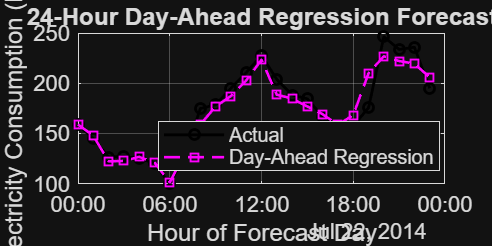


% Plot one complete 24-hour forecast
figure("Position",[100 100 900 450])

plot(timeDayAheadTest(forecastDayRows), ...
     YDayAheadTest(forecastDayRows), ...
     "ko-","LineWidth",1.4, ...
     "MarkerSize",5)

hold on

plot(timeDayAheadTest(forecastDayRows), ...
     predictionDayAheadRegression(forecastDayRows), ...
     "ms--","LineWidth",1.3, ...
     "MarkerSize",5)

xlabel("Hour of Forecast Day")
ylabel("Electricity Consumption (kWh)")
title("24-Hour Day-Ahead Regression Forecast")

legend("Actual","Day-Ahead Regression", ...
    "Location","best")

grid on
set(gca,"FontSize",11)
xtickformat("HH:mm")

% Save the graph
dayAheadRegressionFigurePath = fullfile( ...
    figuresFolder,"day_ahead_regression_forecast.png");

exportgraphics(gcf, ...
    dayAheadRegressionFigurePath, ...
    "Resolution",300)


disp("Day-ahead regression graph saved successfully.")

Day-ahead regression graph saved successfully.


## 14. Train and Evaluate Day-Ahead ANN

%% 14. Train and Evaluate Day-Ahead ANN

% Calculate normalization parameters from training data
dayAheadInputMean = mean(XDayAheadTrain,1);

dayAheadInputStandardDeviation = ...
    std(XDayAheadTrain,0,1);

% Prevent division by zero
dayAheadInputStandardDeviation( ...
    dayAheadInputStandardDeviation == 0) = 1;

% Normalize training, validation and test predictors
XDayAheadTrainNormalized = ...
    (XDayAheadTrain-dayAheadInputMean) ./ ...
    dayAheadInputStandardDeviation;

XDayAheadValidationNormalized = ...
    (XDayAheadValidation-dayAheadInputMean) ./ ...
    dayAheadInputStandardDeviation;

XDayAheadTestNormalized = ...
    (XDayAheadTest-dayAheadInputMean) ./ ...
    dayAheadInputStandardDeviation;

% Combine training and validation observations
XDayAheadDevelopmentANN = [
    XDayAheadTrainNormalized
    XDayAheadValidationNormalized
];

YDayAheadDevelopmentANN = [
    YDayAheadTrain
    YDayAheadValidation
];

% Create the day-ahead ANN
dayAheadANN = fitnet([20 10],"trainscg");

% Disable automatic processing because inputs are normalized manually
dayAheadANN.inputs{1}.processFcns = {};

dayAheadANN.outputs{ ...
    dayAheadANN.numLayers}.processFcns = {};

% Define chronological training and validation indices
numberDayAheadTraining = ...
    size(XDayAheadTrainNormalized,1);

numberDayAheadDevelopment = ...
    size(XDayAheadDevelopmentANN,1);

dayAheadANN.divideFcn = "divideind";

dayAheadANN.divideParam.trainInd = ...
    1:numberDayAheadTraining;

dayAheadANN.divideParam.valInd = ...
    numberDayAheadTraining+1:numberDayAheadDevelopment;

dayAheadANN.divideParam.testInd = [];

% Configure training
dayAheadANN.performFcn = "mse";
dayAheadANN.trainParam.epochs = 300;
dayAheadANN.trainParam.max_fail = 12;
dayAheadANN.trainParam.showWindow = false;

% Reproducible random initialization
rng(42)

% Train the network
fprintf("Day-ahead ANN training inputs: %d\n", ...
    size(XDayAheadDevelopmentANN,2))

Day-ahead ANN training inputs: 6



assert(size(XDayAheadDevelopmentANN,2) == 6, ...
    'Day-ahead ANN must receive exactly six input features.')
[dayAheadANN,dayAheadTrainingRecord] = train( ...
    dayAheadANN, ...
    XDayAheadDevelopmentANN', ...
    YDayAheadDevelopmentANN');

% Forecast the unseen test period
predictionDayAheadANN = ...
    dayAheadANN(XDayAheadTestNormalized')';

% Calculate forecast errors
errorDayAheadANN = ...
    YDayAheadTest-predictionDayAheadANN;

maeDayAheadANN = mean(abs(errorDayAheadANN));

rmseDayAheadANN = ...
    sqrt(mean(errorDayAheadANN.^2));

nonzeroDayAheadANN = abs(YDayAheadTest) > eps;

mapeDayAheadANN = mean( ...
    abs(errorDayAheadANN(nonzeroDayAheadANN) ./ ...
    YDayAheadTest(nonzeroDayAheadANN))) * 100;

% Display test results
fprintf("\nDay-ahead ANN test results:\n")


Day-ahead ANN test results:


fprintf("MAE: %.3f kWh\n",maeDayAheadANN)

MAE: 16.659 kWh


fprintf("RMSE: %.3f kWh\n",rmseDayAheadANN)

RMSE: 23.409 kWh


fprintf("MAPE: %.2f %%\n",mapeDayAheadANN)

MAPE: 9.37 %


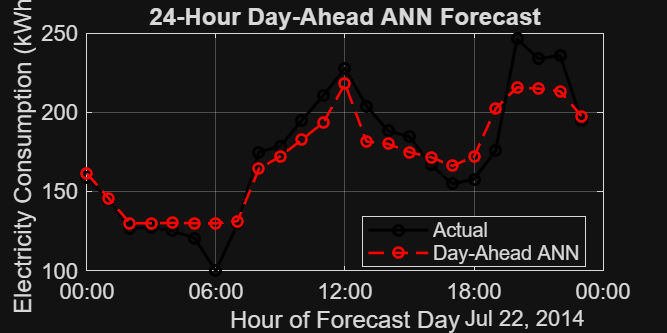


% Plot the same forecast day selected in Section 13
figure("Position",[100 100 900 450])

plot(timeDayAheadTest(forecastDayRows), ...
     YDayAheadTest(forecastDayRows), ...
     "ko-","LineWidth",1.5, ...
     "MarkerSize",5)

hold on

plot(timeDayAheadTest(forecastDayRows), ...
     predictionDayAheadANN(forecastDayRows), ...
     "ro--","LineWidth",1.3, ...
     "MarkerSize",5)

xlabel("Hour of Forecast Day")
ylabel("Electricity Consumption (kWh)")
title("24-Hour Day-Ahead ANN Forecast")

legend("Actual","Day-Ahead ANN", ...
    "Location","best")

grid on
set(gca,"FontSize",11)
xtickformat("HH:mm")

% Save the graph
dayAheadANNFigurePath = fullfile( ...
    figuresFolder,"day_ahead_ann_forecast.png");

exportgraphics(gcf,dayAheadANNFigurePath, ...
    "Resolution",300)


disp("Day-ahead ANN graph saved successfully.")

Day-ahead ANN graph saved successfully.


## 15. Compare Day-Ahead Forecasting Models

%% 15. Compare Day-Ahead Forecasting Models

% ---------------------------------------------------------
% 1. Verify that all required results are available
% ---------------------------------------------------------

assert(exist("predictionDayAheadANN","var") == 1, ...
    'Run Section 14 completely before running Section 15.')

assert(exist("predictionDayAheadRegression","var") == 1, ...
    'Run Section 13 completely before running Section 15.')

assert(dayAheadANN.inputs{1}.size == 6, ...
    'The day-ahead ANN must have exactly six inputs.')

fprintf("Day-ahead ANN input size: %d\n", ...
    dayAheadANN.inputs{1}.size)

Day-ahead ANN input size: 6




% ---------------------------------------------------------
% 2. Create the two historical baseline forecasts
% ---------------------------------------------------------

% Column 1 contains electricity consumption 24 hours earlier
predictionDayAheadYesterday = XDayAheadTest(:,1);

% Column 2 contains electricity consumption 168 hours earlier
predictionDayAheadLastWeek = XDayAheadTest(:,2);


% ---------------------------------------------------------
% 3. Evaluate the same-hour-yesterday baseline
% ---------------------------------------------------------

errorDayAheadYesterday = ...
    YDayAheadTest-predictionDayAheadYesterday;

maeDayAheadYesterday = ...
    mean(abs(errorDayAheadYesterday));

rmseDayAheadYesterday = ...
    sqrt(mean(errorDayAheadYesterday.^2));

nonzeroDayAheadYesterday = ...
    abs(YDayAheadTest) > eps;

mapeDayAheadYesterday = mean( ...
    abs(errorDayAheadYesterday( ...
    nonzeroDayAheadYesterday) ./ ...
    YDayAheadTest(nonzeroDayAheadYesterday))) * 100;


% ---------------------------------------------------------
% 4. Evaluate the same-hour-last-week baseline
% ---------------------------------------------------------

errorDayAheadLastWeek = ...
    YDayAheadTest-predictionDayAheadLastWeek;

maeDayAheadLastWeek = ...
    mean(abs(errorDayAheadLastWeek));

rmseDayAheadLastWeek = ...
    sqrt(mean(errorDayAheadLastWeek.^2));

nonzeroDayAheadLastWeek = ...
    abs(YDayAheadTest) > eps;

mapeDayAheadLastWeek = mean( ...
    abs(errorDayAheadLastWeek( ...
    nonzeroDayAheadLastWeek) ./ ...
    YDayAheadTest(nonzeroDayAheadLastWeek))) * 100;


% ---------------------------------------------------------
% 5. Collect every model's test results
% ---------------------------------------------------------

dayAheadModelNames = [
    "Same Hour Yesterday"
    "Same Hour Last Week"
    "Day-Ahead Regression"
    "Day-Ahead ANN"
];

dayAheadMAE = [
    maeDayAheadYesterday
    maeDayAheadLastWeek
    maeDayAheadRegression
    maeDayAheadANN
];

dayAheadRMSE = [
    rmseDayAheadYesterday
    rmseDayAheadLastWeek
    rmseDayAheadRegression
    rmseDayAheadANN
];

dayAheadMAPE = [
    mapeDayAheadYesterday
    mapeDayAheadLastWeek
    mapeDayAheadRegression
    mapeDayAheadANN
];


% ---------------------------------------------------------
% 6. Create and display the final comparison table
% ---------------------------------------------------------

dayAheadResults = table( ...
    dayAheadModelNames, ...
    dayAheadMAE, ...
    dayAheadRMSE, ...
    dayAheadMAPE, ...
    VariableNames=[ ...
    "Model","MAE_kWh","RMSE_kWh","MAPE_Percent"]);

fprintf("\nDay-ahead forecasting results:\n")


Day-ahead forecasting results:


disp(dayAheadResults)

            Model             MAE_kWh    RMSE_kWh    MAPE_Percent
    ______________________    _______    ________    ____________

    "Same Hour Yesterday"     18.167      25.529         9.931   
    "Same Hour Last Week"      15.92      22.234        8.4327   
    "Day-Ahead Regression"    13.687      19.021        7.4358   
    "Day-Ahead ANN"           16.659      23.409        9.3731   





% ---------------------------------------------------------
% 7. Identify the model with the lowest test RMSE
% ---------------------------------------------------------

[bestDayAheadRMSE,bestDayAheadIndex] = ...
    min(dayAheadRMSE);

bestDayAheadModel = ...
    dayAheadModelNames(bestDayAheadIndex);

fprintf("\nBest day-ahead forecasting model:\n")


Best day-ahead forecasting model:


fprintf("%s\n",bestDayAheadModel)

Day-Ahead Regression



fprintf("Lowest test RMSE: %.3f kWh\n", ...
    bestDayAheadRMSE)

Lowest test RMSE: 19.021 kWh




% ---------------------------------------------------------
% 8. Calculate ANN improvement over the best baseline
% ---------------------------------------------------------

bestDayAheadBaselineRMSE = min( ...
    [rmseDayAheadYesterday,rmseDayAheadLastWeek]);

dayAheadANNImprovement = ...
    (bestDayAheadBaselineRMSE-rmseDayAheadANN) / ...
    bestDayAheadBaselineRMSE*100;

fprintf("\nANN RMSE improvement over best baseline: %.2f %%\n", ...
    dayAheadANNImprovement)


ANN RMSE improvement over best baseline: -5.28 %


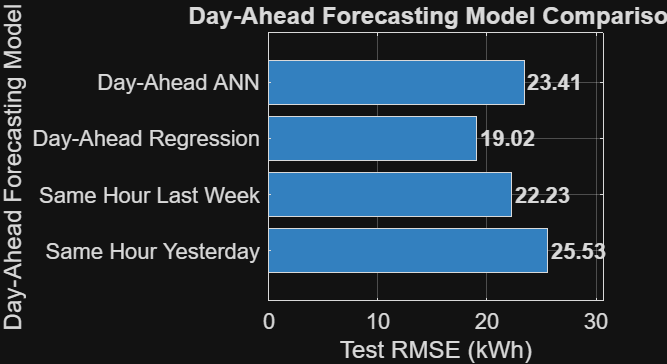


% Positive percentage means ANN performed better.
% Negative percentage means ANN performed worse.


% ---------------------------------------------------------
% 9. Make sure output folders exist
% ---------------------------------------------------------

figuresFolder = fullfile(projectFolder,"figures");
resultsFolder = fullfile(projectFolder,"results");

if ~isfolder(figuresFolder)
    mkdir(figuresFolder)
end

if ~isfolder(resultsFolder)
    mkdir(resultsFolder)
end


% ---------------------------------------------------------
% 10. Create a horizontal RMSE comparison graph
% ---------------------------------------------------------

figure("Position",[100 100 950 520])

dayAheadCategories = categorical( ...
    dayAheadModelNames, ...
    dayAheadModelNames, ...
    "Ordinal",true);

barh(dayAheadCategories,dayAheadRMSE, ...
    "FaceColor",[0.20 0.50 0.75])

xlabel("Test RMSE (kWh)")
ylabel("Day-Ahead Forecasting Model")
title("Day-Ahead Forecasting Model Comparison")
grid on

set(gca,"FontSize",11)

% Add the numerical RMSE value beside each bar
hold on

for modelIndex = 1:length(dayAheadRMSE)

    text(dayAheadRMSE(modelIndex)+0.3, ...
        modelIndex, ...
        sprintf("%.2f",dayAheadRMSE(modelIndex)), ...
        "VerticalAlignment","middle", ...
        "FontWeight","bold", ...
        "FontSize",11)

end

% Add space on the right for numerical labels
xlim([0,max(dayAheadRMSE)*1.20])


% ---------------------------------------------------------
% 11. Save the RMSE comparison graph
% ---------------------------------------------------------

dayAheadComparisonFigurePath = fullfile( ...
    figuresFolder, ...
    "day_ahead_model_comparison.png");

exportgraphics(gcf, ...
    dayAheadComparisonFigurePath, ...
    "Resolution",300)


fprintf("\nRMSE comparison graph saved at:\n")


RMSE comparison graph saved at:


disp(dayAheadComparisonFigurePath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\figures\day_ahead_model_comparison.png




% ---------------------------------------------------------
% 12. Find one complete test day beginning at midnight
% ---------------------------------------------------------

midnightRows = find(hour(timeDayAheadTest) == 0);

if isempty(midnightRows)
    error('No midnight observation was found in the test set.')
end

firstForecastDayStart = midnightRows(1);

if firstForecastDayStart+23 > length(YDayAheadTest)
    error('The test set does not contain a complete 24-hour day.')
end

forecastDayRows = ...
    firstForecastDayStart:firstForecastDayStart+23;

selectedForecastDate = dateshift( ...
    timeDayAheadTest(firstForecastDayStart), ...
    "start","day");

fprintf("Displayed forecast date: %s\n", ...
    string(selectedForecastDate))

Displayed forecast date: 2014-07-22 00:00:00


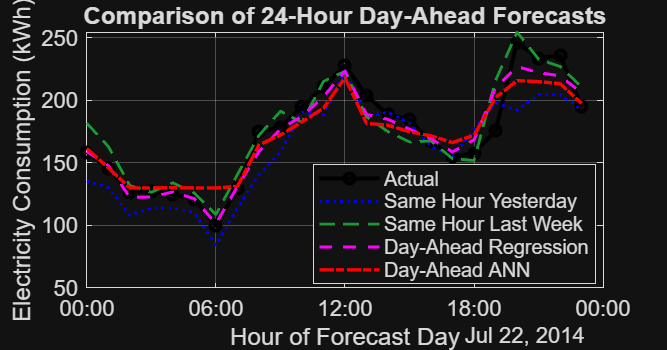



% ---------------------------------------------------------
% 13. Plot actual values and all four forecasts
% ---------------------------------------------------------

figure("Position",[100 100 1050 550])

% Actual electricity consumption
plot(timeDayAheadTest(forecastDayRows), ...
    YDayAheadTest(forecastDayRows), ...
    "k-o", ...
    "LineWidth",2, ...
    "MarkerSize",5)

hold on

% Same-hour-yesterday forecast
plot(timeDayAheadTest(forecastDayRows), ...
    predictionDayAheadYesterday(forecastDayRows), ...
    "b:", ...
    "LineWidth",1.4)

% Same-hour-last-week forecast
plot(timeDayAheadTest(forecastDayRows), ...
    predictionDayAheadLastWeek(forecastDayRows), ...
    "Color",[0.10 0.60 0.20], ...
    "LineStyle","--", ...
    "LineWidth",1.4)

% Linear-regression forecast
plot(timeDayAheadTest(forecastDayRows), ...
    predictionDayAheadRegression(forecastDayRows), ...
    "m--", ...
    "LineWidth",1.5)

% ANN forecast
plot(timeDayAheadTest(forecastDayRows), ...
    predictionDayAheadANN(forecastDayRows), ...
    "r-.", ...
    "LineWidth",1.7)

xlabel("Hour of Forecast Day")
ylabel("Electricity Consumption (kWh)")
title("Comparison of 24-Hour Day-Ahead Forecasts")

legend( ...
    "Actual", ...
    "Same Hour Yesterday", ...
    "Same Hour Last Week", ...
    "Day-Ahead Regression", ...
    "Day-Ahead ANN", ...
    "Location","best")

grid on
set(gca,"FontSize",11)
xtickformat("HH:mm")


% ---------------------------------------------------------
% 14. Save the 24-hour comparison graph
% ---------------------------------------------------------

allDayAheadForecastsPath = fullfile( ...
    figuresFolder, ...
    "all_day_ahead_forecasts.png");

exportgraphics(gcf, ...
    allDayAheadForecastsPath, ...
    "Resolution",300)


fprintf("24-hour comparison graph saved at:\n")

24-hour comparison graph saved at:


disp(allDayAheadForecastsPath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\figures\all_day_ahead_forecasts.png




% ---------------------------------------------------------
% 15. Save the final results as a CSV file
% ---------------------------------------------------------

dayAheadResultsPath = fullfile( ...
    resultsFolder, ...
    "day_ahead_model_comparison.csv");

writetable(dayAheadResults,dayAheadResultsPath)

fprintf("Day-ahead results table saved at:\n")

Day-ahead results table saved at:


disp(dayAheadResultsPath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\results\day_ahead_model_comparison.csv




% ---------------------------------------------------------
% 16. Save the trained models and preprocessing information
% ---------------------------------------------------------

dayAheadModelsPath = fullfile( ...
    resultsFolder, ...
    "day_ahead_models.mat");

save(dayAheadModelsPath, ...
    "dayAheadRegressionModel", ...
    "dayAheadANN", ...
    "dayAheadInputMean", ...
    "dayAheadInputStandardDeviation", ...
    "dayAheadFeatureNames", ...
    "dayAheadResults")

fprintf("Day-ahead trained models saved at:\n")

Day-ahead trained models saved at:


disp(dayAheadModelsPath)

C:\Users\Manita\OneDrive\Documents\MATLAB\Load_Forecasting_Project\results\day_ahead_models.mat



fprintf("\nSection 15 completed successfully.\n")


Section 15 completed successfully.
